cd /Users/serg/github_projects/QASS_SVM
rng('default')
rng(1234)
X1 = randn (50 ,2) + 1;
X2 = randn (50 ,2) - 1;
M1 = mean(X1);
M2 = mean(X2);
C = (M1 + M2)/2;
V = M1 - M2;
VN = [-V(2), V(1)];

blackColor = [0 0 0];
grayColor = [.7 .7 .7];

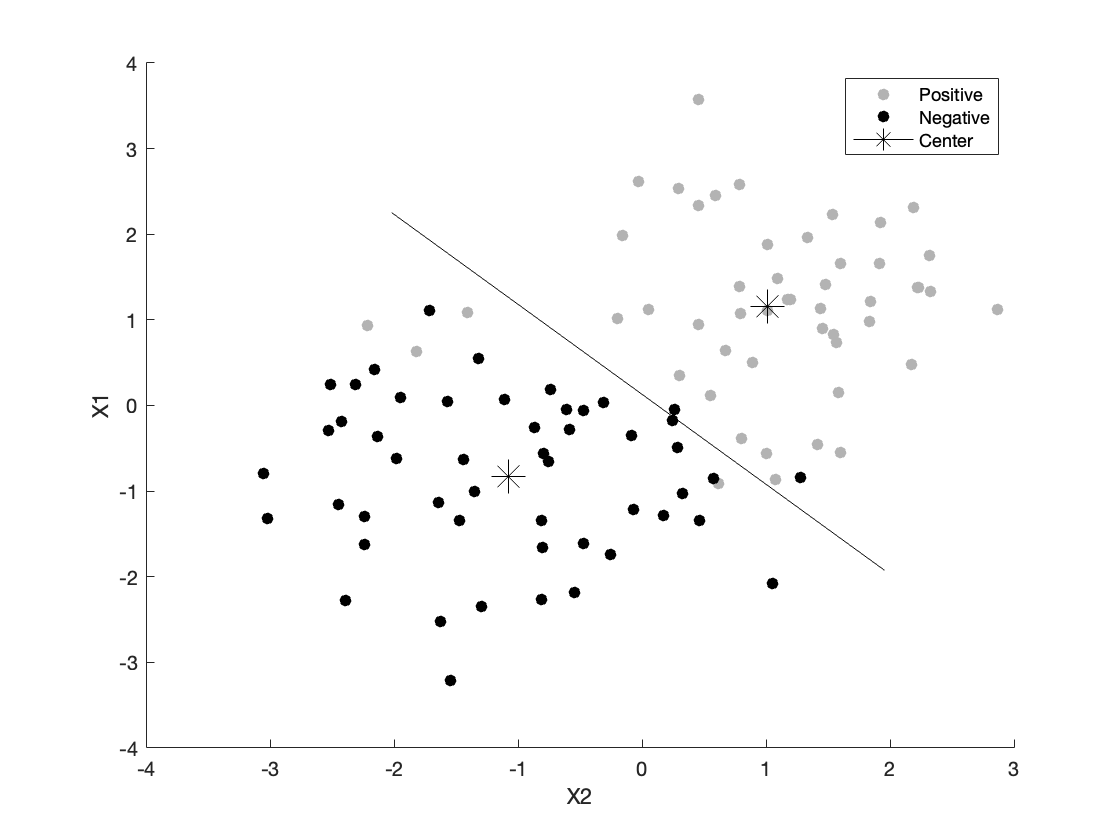

figure ;
hold on;
scatter(X1 (: ,1), X1 (: ,2), [], grayColor,'o','filled') ;
scatter(X2 (: ,1), X2 (: ,2), [], blackColor,'o', 'filled') ;
plot(M1(1), M1(2), 'Color', blackColor, 'Marker','*', 'MarkerSize', 15);
plot(M2(1), M2(2), 'Color', blackColor, 'Marker','*', 'MarkerSize', 15);
plot([C(1) + VN(1) C(1)-VN(1)], [C(2) + VN(2) C(2)-VN(2)],'Color', blackColor)
xlabel('X2') 
ylabel('X1') 
legend('Positive','Negative', 'Center')
hold off;

% store image 
f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_111.png','Resolution',300)